# Try2 version3

HPC】高性能数值计算-求解拉普拉斯方程

[https://zhuanlan.zhihu.com/p/144331014](https://zhuanlan.zhihu.com/p/144331014)

原函数为 u=sinx+siny

其拉普拉斯变换为 f=-u=-sinx-siny

## Paramètre

x=10;   %longueur en x
y=10;   %longueur en y
h=1;  %pas
m=0:h:x;
n=0:h:y;
T=zeros(length(n),length(m))

T =      0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


length(T)

ans = 11

## Condition frontière


T(1,:)=10;
T(:,1)=10;
T(length(m),:)=5;
T(:,length(n))=1;
T1=T

T1 =     10    10    10    10    10    10    10    10    10    10     1
    10     0     0     0     0     0     0     0     0     0     1
    10     0     0     0     0     0     0     0     0     0     1
    10     0     0     0     0     0     0     0     0     0     1
    10     0     0     0     0     0     0     0     0     0     1
    10     0     0     0     0     0     0     0     0     0     1
    10     0     0     0     0     0     0     0     0     0     1
    10     0     0     0     0     0     0     0     0     0     1
    10     0     0     0     0     0     0     0     0     0     1
    10     0     0     0     0     0     0     0     0     0     1


[xq,yq] = meshgrid(m, n)

xq =      0     1     2     3     4     5     6     7     8     9    10
     0     1     2     3     4     5     6     7     8     9    10
     0     1     2     3     4     5     6     7     8     9    10
     0     1     2     3     4     5     6     7     8     9    10
     0     1     2     3     4     5     6     7     8     9    10
     0     1     2     3     4     5     6     7     8     9    10
     0     1     2     3     4     5     6     7     8     9    10
     0     1     2     3     4     5     6     7     8     9    10
     0     1     2     3     4     5     6     7     8     9    10
     0     1     2     3     4     5     6     7     8     9    10


yq =      0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3
     4     4     4     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5     5     5     5
     6     6     6     6     6     6     6     6     6     6     6
     7     7     7     7     7     7     7     7     7     7     7
     8     8     8     8     8     8     8     8     8     8     8
     9     9     9     9     9     9     9     9     9     9     9


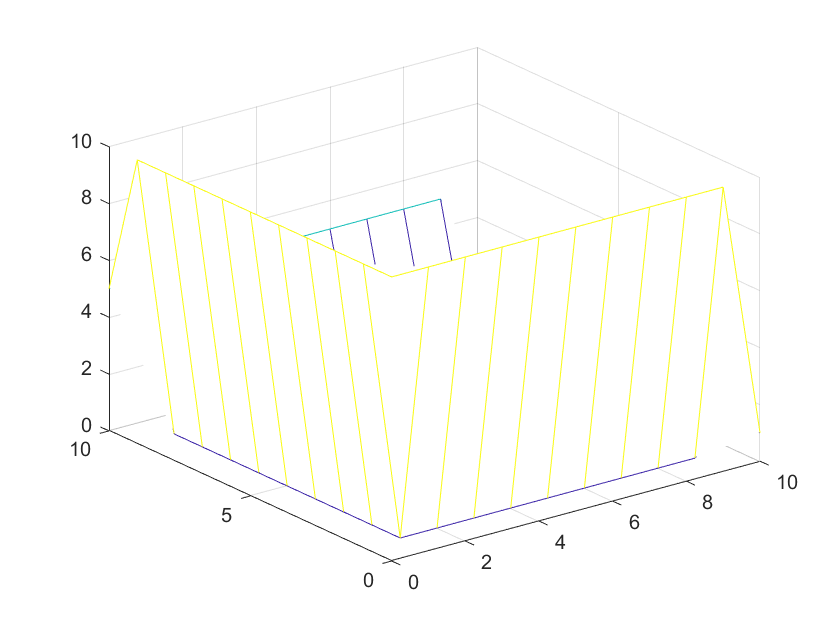

mesh(xq,yq,T1)

## Gauss-Seidel

% !!!!
% if the matrix is not square but a rectangle,
% you must exchange the position of m and n in the codes below
e=1; count=0;
while e>=0.00001
    count=count+1;
    T1(2:length(m)-1,2:length(n)-1)=(T(2:length(m)-1,1:length(n)-2) ...%West
        +T(2:length(m)-1,3:length(n)) ...%East
        +T(1:length(m)-2,2:length(n)-1) ...%North
        +T(3:length(n),2:length(n)-1))/4-(h^2*.2)/4; %South
    e=abs(max(max(T1-T)));
    T=T1;
end
count

count = 214

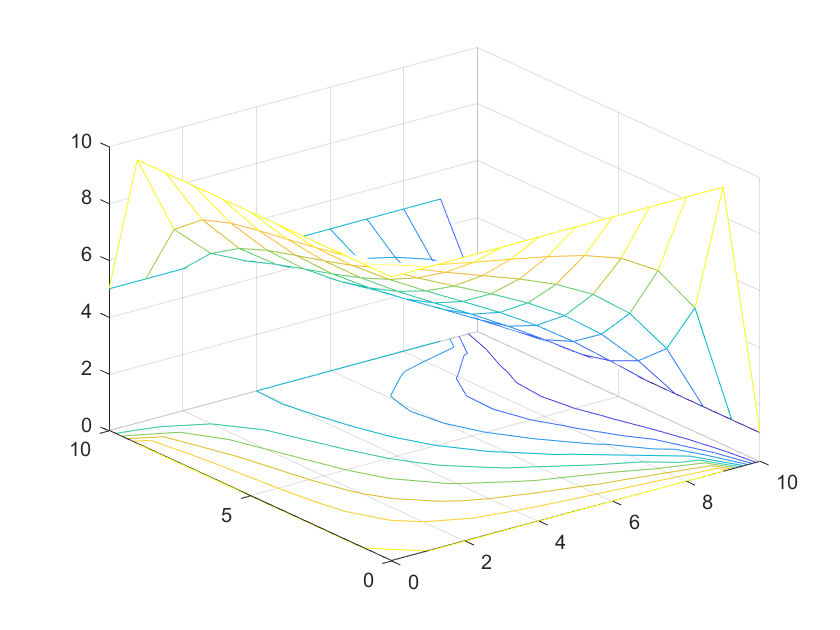


meshc(xq,yq,T)

## fct u (original) et f (son laplacien)

function res = u(x,y)
res=sin(x)+sin(y);
end
function res=f(x,y)
res=-sin(x)-sin(y);
end